## SPANNLOSS PREDICTION USING MULTIPLE REGRESSION

#### **CREATING PARAMETERS**

This section is to make the parameters for the model. The len variable is used to specify the no of cases/rows we want. The pararmeters are randomly created in the 'createParameters' function. The spanloss is calculated by the following relationship 0.275*linklength.

Parameters are , Link Type , Age , Link Length and Span Loss(to train the model)

len = 5000;
[x] = createParameters(len);
save('SpanLossTrainingData.mat','x');

#### **LOADING THE PARAMETERS**

This section is used to load parameter and divide it into paramteres (x) and trainnig parameter (y).

testvar = matfile('SpanLossTrainingData.mat');
varx = testvar.x;
len_varx = length(varx);
x = varx(:,1:3);
y = varx(:,4);
m = length(x);
X = [ones(m, 1), x(:,:)]; 
theta = [0;0;0;0]; 
% for gradient descent
iterations = 5000;
alpha = 0.00000009;

#### **PLOTING THE GRAPHS**

The graphs are plotted to demonstrate the type of relationship between spannloss and the various parameters.

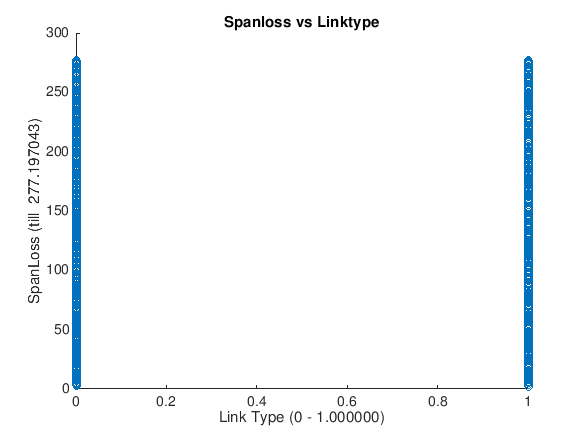

x_linktype = x(:,1);
x_linkage = x(:,2);
x_linklength = x(:,3);

%   Spanloss vs LinkType
%plot(x_linktype, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
scatter(x_linktype,y);
xlabel(sprintf('Link Type (0 - %f)', max(x_linktype)));
ylabel(sprintf('SpanLoss (till  %f)', max(y)));
title ('Spanloss vs Linktype');

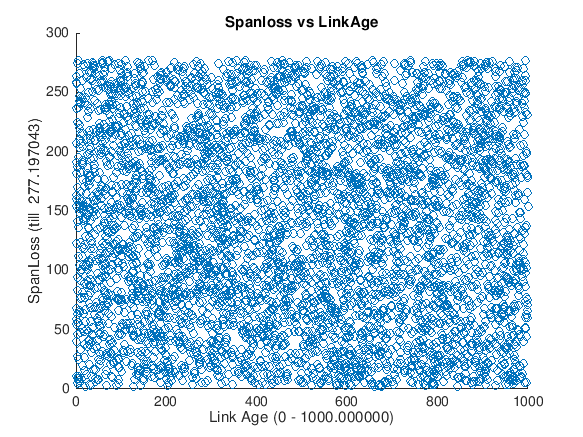


%   Spanloss vs LinkAge
%plot(x_linkage, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
scatter(x_linkage,y);
xlabel(sprintf('Link Age (0 - %f)', max(x_linkage)));
ylabel(sprintf('SpanLoss (till  %f)', max(y)));
title ('Spanloss vs LinkAge');

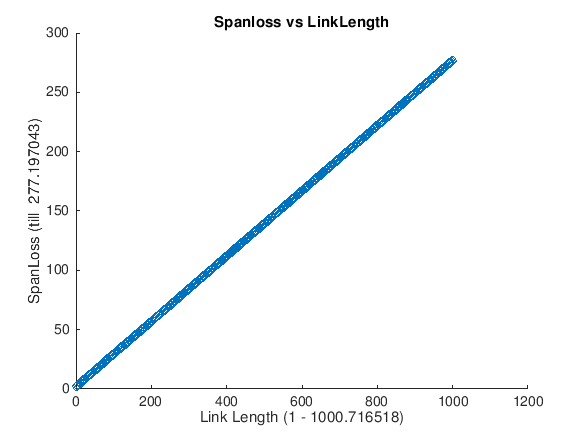



%   Spanloss vs LinkLength
%plot(x_linklength, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
scatter(x_linklength,y);
xlabel(sprintf('Link Length (1 - %f)', max(x_linklength)));
ylabel(sprintf('SpanLoss (till  %f)', max(y)));
title ('Spanloss vs LinkLength');

### **1.1 GRADIENT DESCENT METHOD**

This section is to compute the cost (J) and gradient descent.

% choosing the Alpha and Iterations
[alpha,iterations] =  retAlphaAndIt(X,y,theta);
disp('Alpha = ');

Alpha = 


disp(alpha);

   1.0000e-06



disp('Iterations = ');

Iterations = 


disp(iterations);

       50000



cost = computeCost(X, y, theta);
fprintf('cost is %f\n',cost);

cost is 28004.947599



%disp(theta);
theta = gradientDescent(X, y, theta, alpha, iterations);
disp('Theta  = ');

Theta  = 


disp(theta);

   -0.0051
    1.4085
   -0.0014
    0.3916



P= 383.138349


P= 384.546826


**Rough Section** -> To check the gradient decent and see the prediction.

% gradient descent 
disp(theta);

     0
     0
     0
     0



theta = gradientDescent(X, y, theta, alpha, 100000);
disp(theta);

    0.0003
    0.0001
    0.0017
    0.2767




prediction =  [1 1 100 978.8]*theta;
fprintf("P= %f\n" , prediction );

P= 271.015811


### **1.2 Predicting the Result using Gradient Descent**

fprintf("\nPrediction through gradient descent method = %f\n" , predictResult(theta));

%prediction =  [1 1 100 978.8]*theta;
%fprintf("P= %f\n" , prediction );

P= 41.482414


### **1.3 Visualising / Checking the correct working of Gradient Descent** 

The graph of cost J vs number of iterations is plotted to visualise and check whether our Gradient Descent is working properly. The alpha and num_iters can be changed by sliders and drop down menu,

It the cost J is gradually decreasing with increasing of num_of_iters then the algo is working fine.

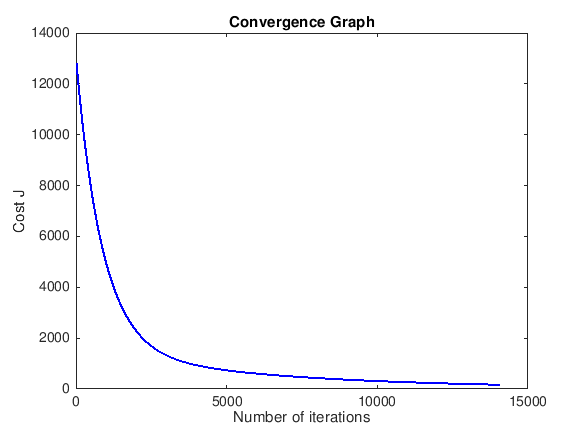

alpha = 0.000000001;
num_iters = 14100;

% Init Theta and Run Gradient Descent 
theta = zeros(4, 1);
[~, J_history] = gradientDescent(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');
title('Convergence Graph');

### **2 .Normal Equation implementation**

This is another approach of solving for theta (solves theta analytically). It doesn't need alpha or iterations. It becomes slow if n (no of features) is very large (i.e, n>10,000).

normalTheta = normalEquation(X,y);
disp("NormalTheta = ");

NormalTheta = 


disp(normalTheta);

    2.0000
   -0.0000
    0.0000
    0.2750



### **PREDICTING THE RESULT USING NORMAL EQUATION**

fprintf("\nPrediction through normal eq method = %f\n" , predictResult(normalTheta));

Enter the parameters 

Prediction through normal eq method = 271.170000



% example
%prediction2 =  [1 1 100 978.8]*normaltheta;
%fprintf("P2= %f\n" , prediction2 );